# Transducer Design

Transducer 1

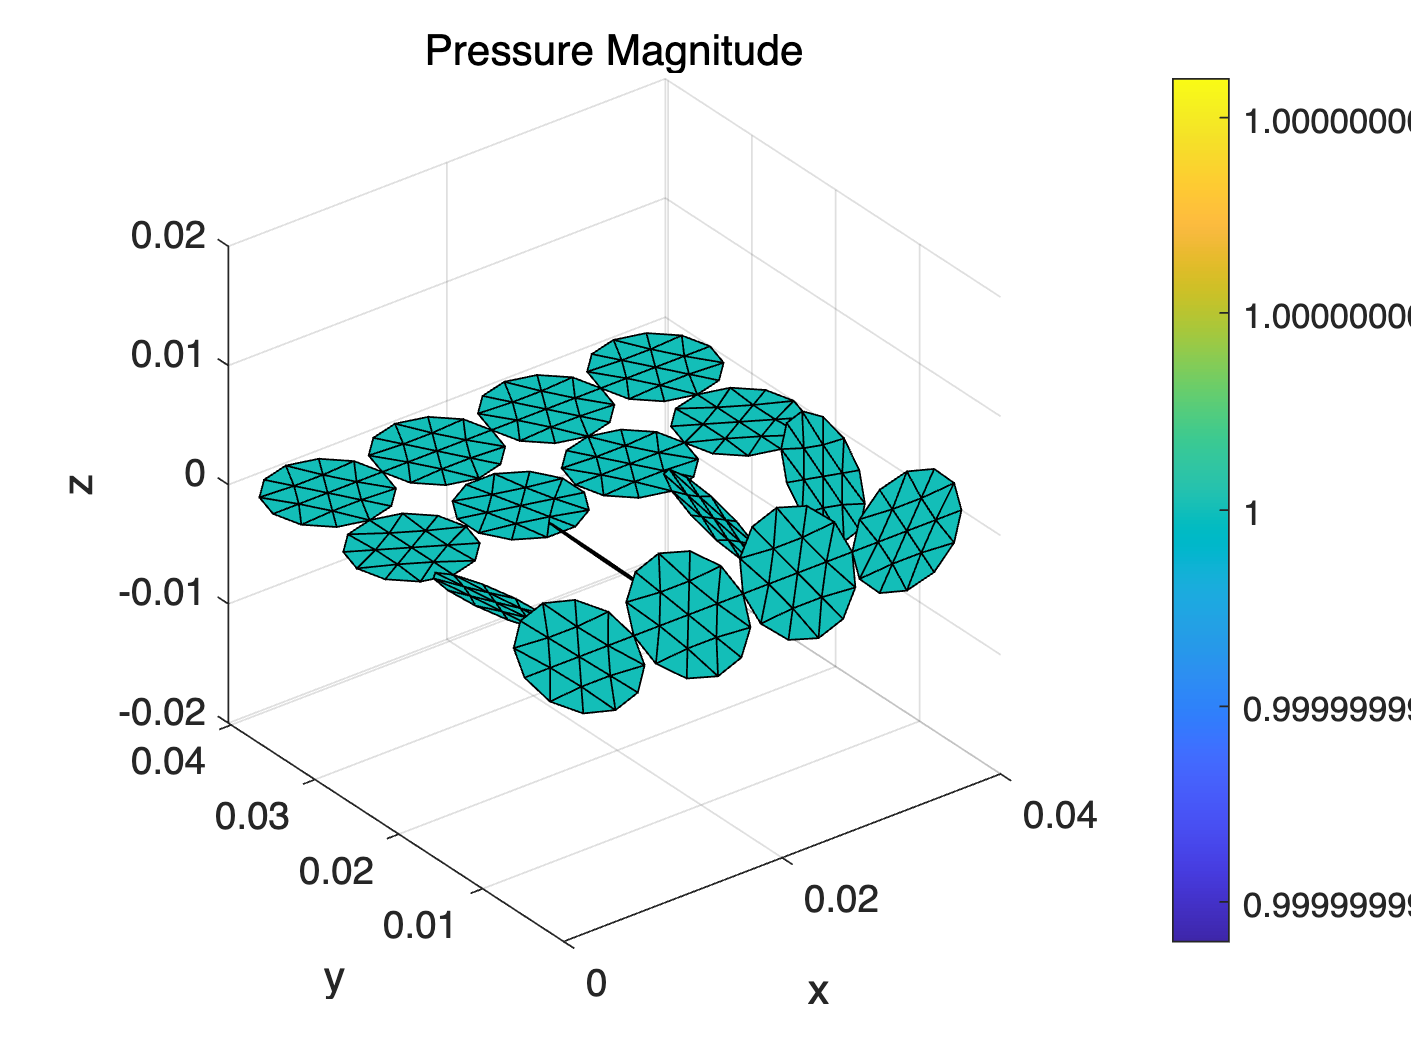

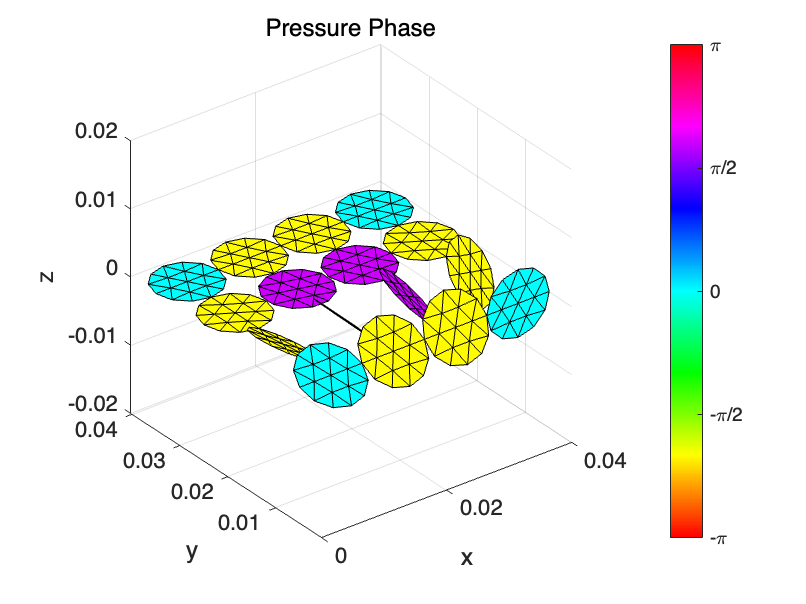

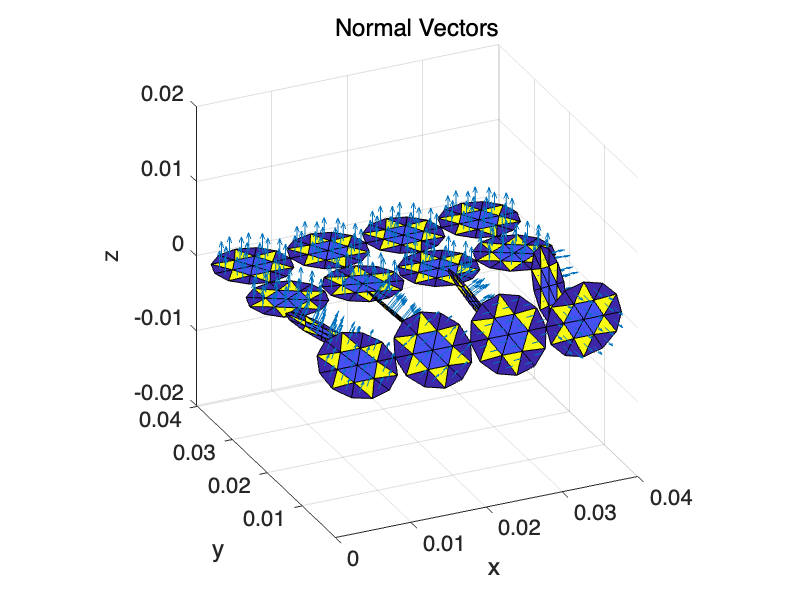

transducer_info = [];

transducer_info.Frequency = 4e4;
transducer_info.Pressure = 1;
% transducer_info.Phase = 0;
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;

transducer_info.rotate = [30, 0, 0];
transducer_info.position = [0.005, 0.005, 0];
transducer_info.Phase = 0;
transducer_object(1) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [45, 0, 0];
transducer_info.position = [0.015, 0.005, 0];
transducer_info.Phase = 2.0924;
transducer_object(2) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [60, 0, 0];
transducer_info.position = [0.025, 0.005, 0];
transducer_info.Phase = 2.0924;
transducer_object(3) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [90, 0, 0];
transducer_info.position = [0.035, 0.005, 0];
transducer_info.Phase = 0;
transducer_object(4) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 30, 0];
transducer_info.position = [0.005, 0.015, 0];
transducer_info.Phase = 2.0924;
transducer_object(5) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 45, 0];
transducer_info.position = [0.015, 0.015, 0];
transducer_info.Phase = 4.3763;
transducer_object(6) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 60, 0];
transducer_info.position = [0.025, 0.015, 0];
transducer_info.Phase = 4.3763;
transducer_object(7) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 90, 0];
transducer_info.position = [0.035, 0.015, 0];
transducer_info.Phase = 2.0924;
transducer_object(8) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 30];
transducer_info.position = [0.005, 0.025, 0];
transducer_info.Phase = 2.0924;
transducer_object(9) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 45];
transducer_info.position = [0.015, 0.025, 0];
transducer_info.Phase = 4.3763;
transducer_object(10) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 60];
transducer_info.position = [0.025, 0.025, 0];
transducer_info.Phase = 4.3763;
transducer_object(11) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 90];
transducer_info.position = [0.035, 0.025, 0];
transducer_info.Phase = 2.0924;
transducer_object(12) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 0];
transducer_info.position = [0.005, 0.035, 0];
transducer_info.Phase = 0;
transducer_object(13) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 0];
transducer_info.position = [0.015, 0.035, 0];
transducer_info.Phase = 2.0924;
transducer_object(14) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 0];
transducer_info.position = [0.025, 0.035, 0];
transducer_info.Phase = 2.0924;
transducer_object(15) = PFC_Make3DTransducer(transducer_info);

transducer_info.rotate = [0, 0, 0];
transducer_info.position = [0.035, 0.035, 0];
transducer_info.Phase = 0;
transducer_object(16) = PFC_Make3DTransducer(transducer_info);

PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = 0 : 0.1e-3 : 40e-3;          % Simulation Area
reading_pos_y = 0 : 0.1e-3 : 40e-3;          % Simulation Area
reading_pos_z = 0 : 0.1e-3 : 40e-3;          % Simulation Area

## Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.02, reading_pos_z);

Started at 2024-04-29 16:19:35
Finished at 2024-04-29 16:20:00
Progressed time : 00:00:25


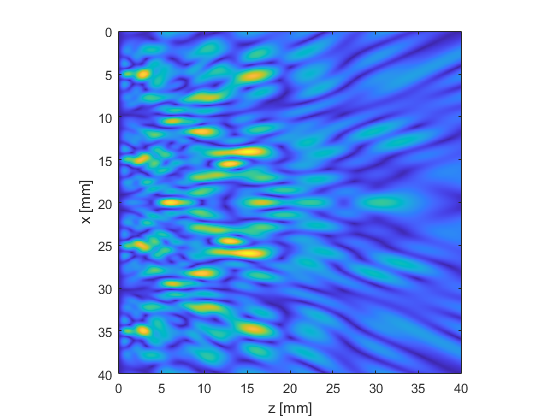


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
xlabel('z [mm]');
ylabel('x [mm]');



% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.03);

Started at 2024-04-29 16:20:00
Finished at 2024-04-29 16:20:27
Progressed time : 00:00:26


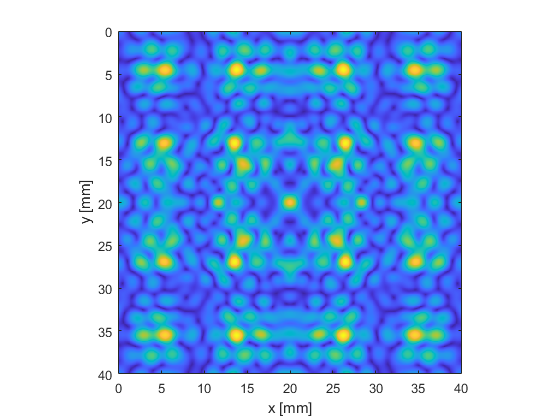


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
xlabel('x [mm]');
ylabel('y [mm]');